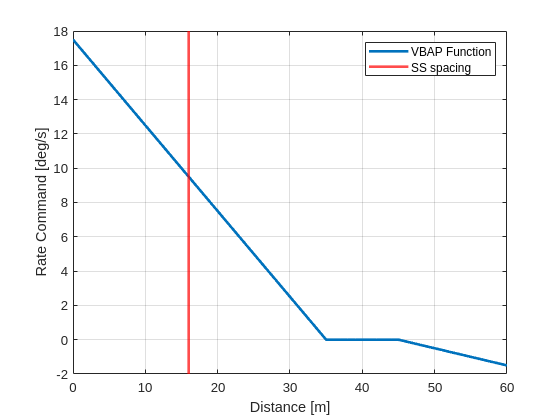

% VBAP spring

dist_boat = 0:1:60;

d0 = 45;
dmin = 35;
dmax = 60;
ko = 0.1;
k2 = 0.5;

head_boat = -10;
turn_boat = zeros(size(dist_boat));

 for ii=1:numel(dist_boat)
        if dist_boat(ii) <= dmax && dist_boat(ii) >= d0
         turn_boat(ii) = ko*(dist_boat(ii)-d0)*sign(head_boat);
         elseif dist_boat(ii) < dmin
         turn_boat(ii) = k2*sign(head_boat)*(dist_boat(ii) - dmin);
        else
        turn_boat(ii) = 0;
        end
   
 end
    figure()
    clf
 plot(dist_boat,turn_boat,'LineWidth',2)
 grid on
 hold on
 xlabel('Distance [m]')
 ylabel('Rate Command [deg/s]')
 xline(16,'r','linewidth',2)
 legend('VBAP Function','SS spacing')